**Gruppo 2 (esercizio 2)**

Considerare vettori con un numero n di componenti da 2 a 20, le cui componenti sono punti equidistanti nell'intervallo [-1,1], oppure un intervallo [a, b] con a, b numeri reali. Calcolare le tre norme vettoriali al crescere di n e farne il confronto analizzando il grafico dei risultati.

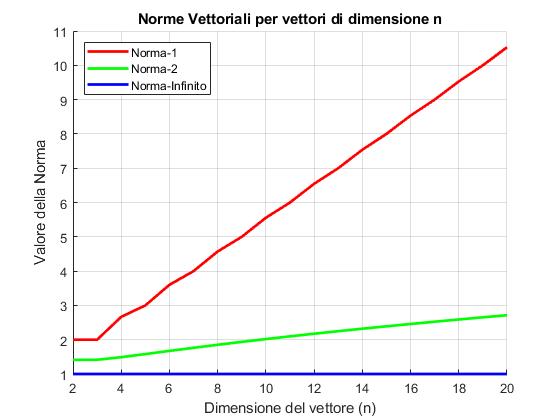

g2e2(-1,1, 2, 20)

**Gruppo 3** (esercizio 2)

          Norm1     Norm2      Inf      Frobenius
          ______    ______    ______    _________

    2        1.5    1.2676       1.5     1.2693  
    3     1.8333    1.4083    1.8333     1.4136  
    4     2.0833    1.5002    2.0833     1.5097  
    5     2.2833    1.5671    2.2833     1.5809  
    6       2.45    1.6189      2.45      1.637  
    7     2.5929    1.6609    2.5929     1.6831  
    8     2.7179    1.6959    2.7179     1.7221  
    9      2.829    1.7259     2.829     1.7559  
    10     2.929    1.7519     2.929     1.7855  

          Norm1    Norm2     Inf    Frobenius
          _____    _

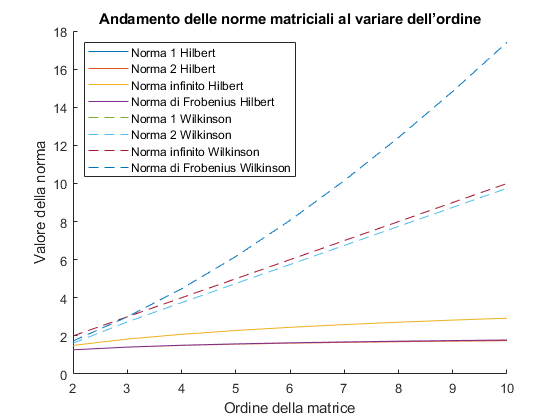

g3e2(2,10)

**Gruppo 4 (esercizio 1)**

Studiare, analizzando i risultati, l'indice di condizionamento di alcune famiglie di matrici al crescere dell'ordine n da 2 a 10 rispetto a 2 delle norme studiate.

Fare il grafico dell'andamento dell'indice di condizionamento, confrontare, analizzare e commentare i risultati.

Usare la scala logaritmica sull'asse delle ordinate per avere un grafico migliore

            Norm2        NormInf  
          __________    __________

    2         19.281            27
    3         524.06           748
    4          15514         28375
    5     4.7661e+05    9.4366e+05
    6     1.4951e+07     2.907e+07
    7     4.7537e+08    9.8519e+08
    8     1.5258e+10    3.3873e+10
    9     4.9315e+11    1.0996e+12
    10    1.6025e+13    3.5352e+13
    11    5.2202e+14    1.2295e+15
    12    1.6212e+16     3.842e+16
    13    4.7864e+17    7.4907e+17
    14    2.5515e+17    1.5679e+18
    15     2.496e+17    1.2092e+18
    16    4.8875e+17    7.1626e+19
    17    4.5144e+17    1.2269e+19
    18      

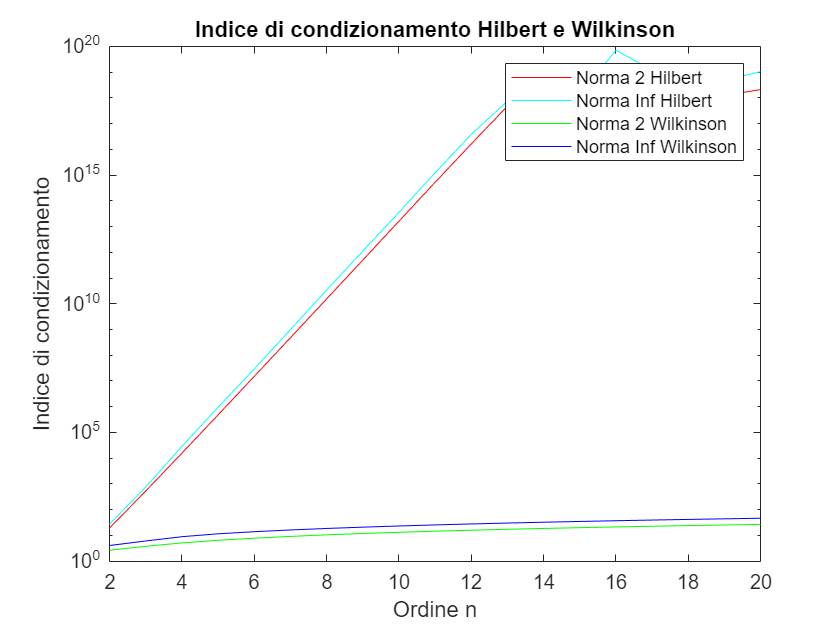

g4e1(2,20)

**Gruppo 5 (esercizio 2)**

Calcolare il determinante della matrice di una matrice A con ordine n > 10.

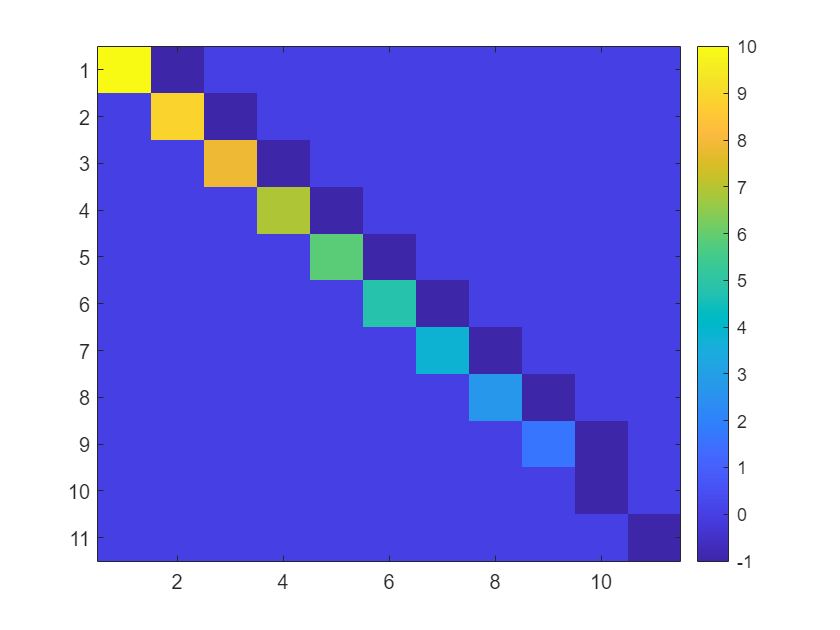

A = wilki(11);
[A1, detA1] = det_gauss_pp(A);
imagesc(A1); colorbar

disp(detA1);

    -2314230



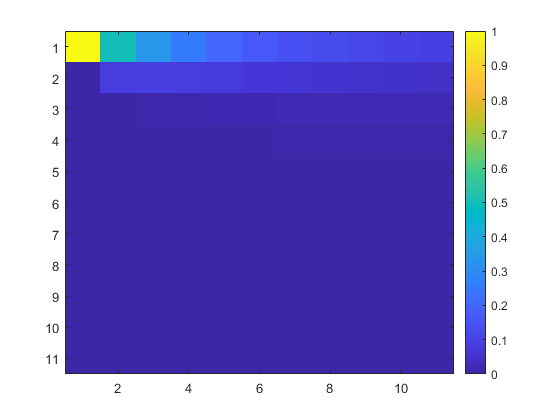

B = hilb(11);
[B1, detB1] = det_gauss_pp(B);
imagesc(B1); colorbar

disp(detB1)

   3.0267e-65



**Guppo 6 **(esercizio 2)

Metodo di Jacobi:
Soluzione:     1.0000
    1.0000
    1.0000

Iterazioni: 84
Metodo di Gauss-Seidel:
Soluzione:     1.0000
    1.0000
    1.0000

Iterazioni: 145


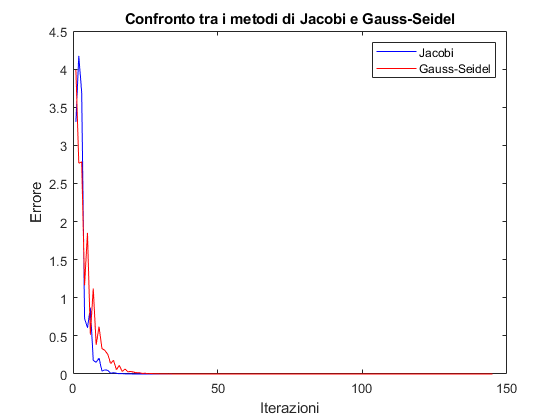

A=[7,6,9;4,5,-4;-7,-3,8];
b=[22,5,-2];
g6e2(A, b, 1000, 1e-16)

Metodo di Jacobi:
Soluzione:      1
     1
     1
     1

Iterazioni: 30
Metodo di Gauss-Seidel:
Soluzione:      1
     1
     1
     1

Iterazioni: 28


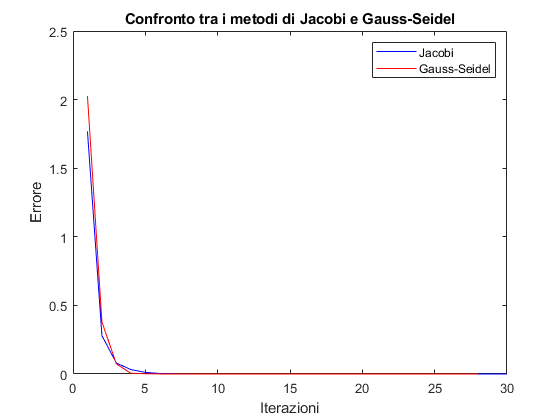

A=[-4,-1,1,1;0,-4,-1,1;-1,-1,4,1;1,-1,0,4];
b=[-3,-4, 3, 4];
g6e2(A, b, 1000, 1e-16)

Metodo di Jacobi:
Soluzione:      1
     1
     1

Iterazioni: 47
Metodo di Gauss-Seidel:
Soluzione:      1
     1
     1

Iterazioni: 11


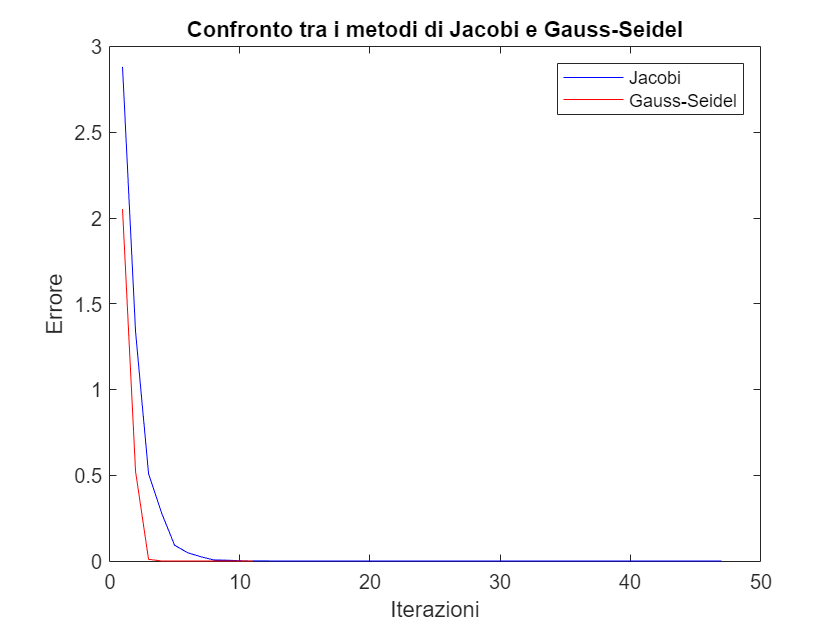

A=[4,1,1;2,-9,0;0,-8,-6];
b=[6, -7, -14];
g6e2(A, b, 1000, 1e-16)

**Gruppo 7 **(esercizio 2)

% Matrice a Freccia
n = 15;  % per n > 12
A = 19 * eye(n);  % matrice diagonale a 19
A(1, 2:n) = -1;  % prima riga restante a -1
A(2:n, 1) = 1;  % prima colonna restante a 1

**Matrice Freeccia:**

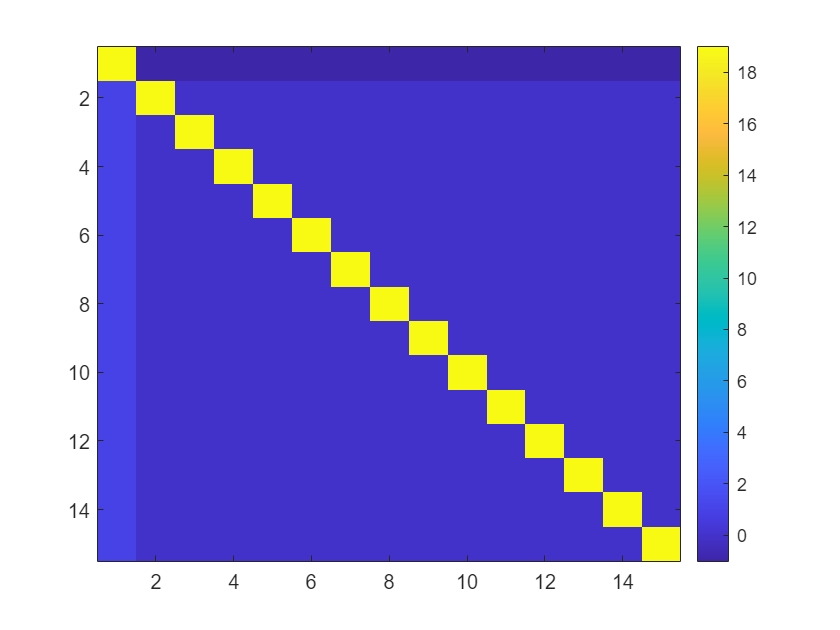

imagesc(A); colorbar

b = zeros(n,1) + 20;
b(1)=5;
[iter,e]=jacobi(A,b,ones(n,1),1000,1e-6)

iter =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


e = 1

**Gruppo 7  (esercizio 3)**

Considerare il sistema lineare con matrice A=[0.96326,0.81321;0.81321,0.68654] e vettore dei termini noti b=[0.88824;0.74988].

Risovi i punti A,B,C,D.

% Definizione della matrice A e del vettore b
A = [0.96326, 0.81321; 0.81321, 0.68654];
b = [0.88824; 0.74988];

% Verifica se A è definita positiva
isPositive = issymmetric(A) && all(eig(A) > 0);
if isPositive
    % Metodo di Cholesky
    x_cholesky = cholesky(A,b);
    % Calcolo della norma del residuo per Cholesky (norma 2)
    residuo_cholesky = norma(A*x_cholesky - b,2); 

    % Stampa dei risultati del metodo di Cholesky
    fprintf('Soluzione Cholesky: [%f; %f]\n', x_cholesky);
    fprintf('Norma del Residuo Cholesky: %f\n\n', residuo_cholesky);
else
    disp('La matrice A non è definita positiva')
    return
end

Soluzione Cholesky: [0.394728; 0.624703]


Norma del Residuo Cholesky: 0.000000



% Calcolo della matrice di iterazione per Gauss-Seidel
D = diag(diag(A));
L = tril(A, -1);
U = triu(A, 1);
M_GS = (D + L)^-1 * U; 

% Calcolo della norma della matrice di iterazione (norma 2)
norm_M_GS = norm(M_GS); 

% Calcolo del raggio spettrale della matrice di iterazione
raggio_spettrale_M_GS = max(abs(eig(M_GS)));

% Definizione dei vettori iniziali
x0_vec = [[0.33116; 0.7], [0; 0], [1; 1]];

% Iterazione per ogni vettore iniziale
n = size(x0_vec, 2);
for i = 1 : n
    x0 = x0_vec(:, i);
    [x_gauss_seidel, iter, error] = gauss_seidel(A, b, x0, 1000, 1e-6);

    % Stampa dei risultati
    fprintf('Vettore iniziale: [%f; %f]\n', x0);
    fprintf('Soluzione Gauss-Seidel: [%f; %f]\n', x_gauss_seidel);
    fprintf('Iterazioni Gauss-Seidel: %d\n', iter);
    fprintf('Norma del Residuo Gauss-Seidel: %f\n\n', norm(A*x_gauss_seidel - b));
    fprintf('------------------------------------------');
end

Vettore iniziale: [0.331160; 0.700000]


Soluzione Gauss-Seidel: [0.331160; 0.699999]


Iterazioni Gauss-Seidel: 1


Norma del Residuo Gauss-Seidel: 0.000001



------------------------------------------

Vettore iniziale: [0.000000; 0.000000]


Soluzione Gauss-Seidel: [0.917347; 0.005657]


Iterazioni Gauss-Seidel: 1000


Norma del Residuo Gauss-Seidel: 0.000005



------------------------------------------

Vettore iniziale: [1.000000; 1.000000]


Soluzione Gauss-Seidel: [0.080758; 0.996601]


Iterazioni Gauss-Seidel: 1000


Norma del Residuo Gauss-Seidel: 0.000003



------------------------------------------

% Calcolo dell'indice di condizionamento di A
cond_A = cond(A); % ||A|| * ||inv(A)||
% Stampa dei risultati
fprintf('Indice di condizionamento di A: %f\n', cond_A);

Indice di condizionamento di A: 452408.956885


fprintf('Norma della matrice di iterazione: %f\n', norm_M_GS);

Norma della matrice di iterazione: 1.308702


fprintf('Raggio spettrale della matrice di iterazione: %f\n', raggio_spettrale_M_GS);

Raggio spettrale della matrice di iterazione: 0.999991


**Gruppo 8 (esercizio 1)**

Verificare la bontà del metodo di interpolazione di Lagrange (o di Newton) su alcune

funzioni, di cui si conosce la formula analitica, considerando tabulati con 5, 6, 11, 12, 20, 25

punti equidistanti. Analizzare il grafico degli errori. Costruire la tabella contenente la norma

dell'errore.

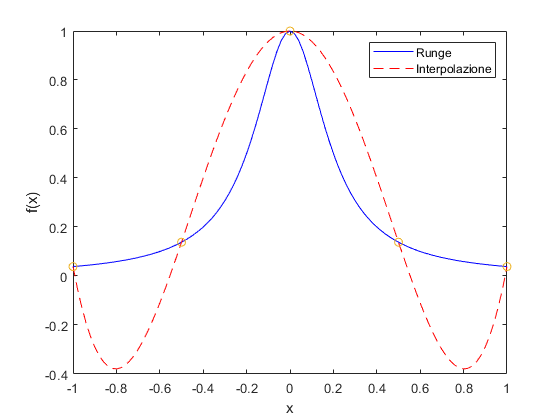

y1 = @(x) 1./(1 + 25*x.^2); % Runge
y2 = @(x) x./(1 + x.^2);

% Punti per la visualizzazione del polinomio interpolante
x = linspace(-1, 1, 101);
% Tabella di 5 punti 
table = funTable(y1, -1, 1, 5, 1);
yi = lagrange(x, table);
plot(x, y1(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('Runge', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

      x        f(x)         yi         Errore  
    _____    ________    _________    _________

       -1    0.038462     0.038462            0
    -0.98    0.039984    -0.049562     0.089546
    -0.96    0.041597     -0.12572      0.16732
    -0.94    0.043309     -0.19063      0.23394
    -0.92    0.045126      -0.2449      0.29003
     -0.9    0.047059     -0.28912      0.33618
    -0.88    0.049116     -0.32387      0.37299
    -0.86    0.051308     -0.34972      0.40103
    -0.84    0.053648     -0.36722      0.42087
    -0.82    0.056148      -0.3769      0.43305
     -0.8    0.058824     -0.37931      0.43813
    -0.78     0.06169     -0.37495      0.43664
    -0.76    0.064767     -0.36433       0.4291
    -0.74    0.068074     -0.34794      0.41601
    -0.72    0.071633     -0.32625      0.39788
     -0.7    0.075472     -0.29973      0.37521

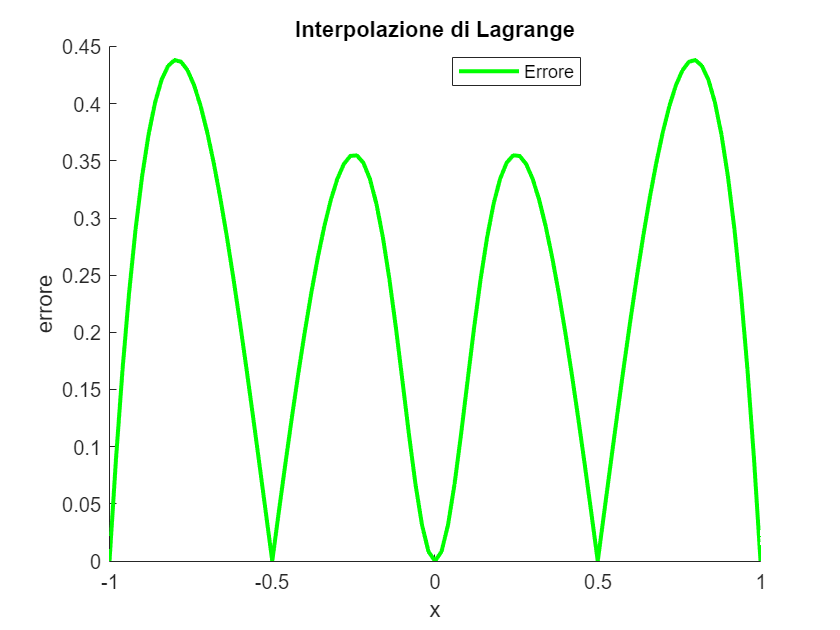


Errore Norma: 2.7919


errLagrange(x, yi, y1);

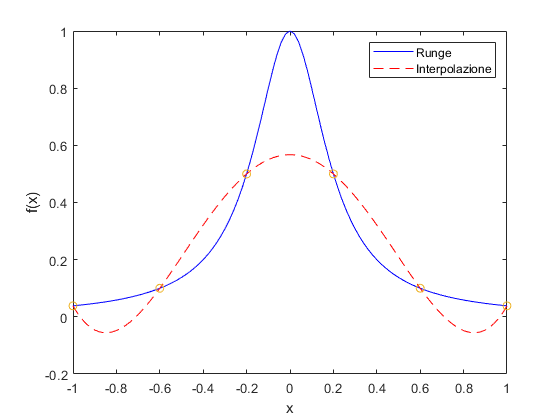

% Tabella di 6 punti 
table = funTable(y1, -1, 1, 6, 1);
yi = lagrange(x, table);
plot(x, y1(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('Runge', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

      x        f(x)         yi         Errore  
    _____    ________    _________    _________

       -1    0.038462     0.038462            0
    -0.98    0.039984     0.013693     0.026292
    -0.96    0.041597     -0.00692     0.048517
    -0.94    0.043309      -0.0236     0.066909
    -0.92    0.045126    -0.036566     0.081693
     -0.9    0.047059    -0.046034     0.093092
    -0.88    0.049116    -0.052212      0.10133
    -0.86    0.051308    -0.055307      0.10662
    -0.84    0.053648     -0.05552      0.10917
    -0.82    0.056148    -0.053046      0.10919
     -0.8    0.058824    -0.048077       0.1069
    -0.78     0.06169      -0.0408      0.10249
    -0.76    0.064767    -0.031397     0.096164
    -0.74    0.068074    -0.020046     0.088119
    -0.72    0.071633     -0.00692     0.078553
     -0.7    0.075472    0.0078125     0.067659

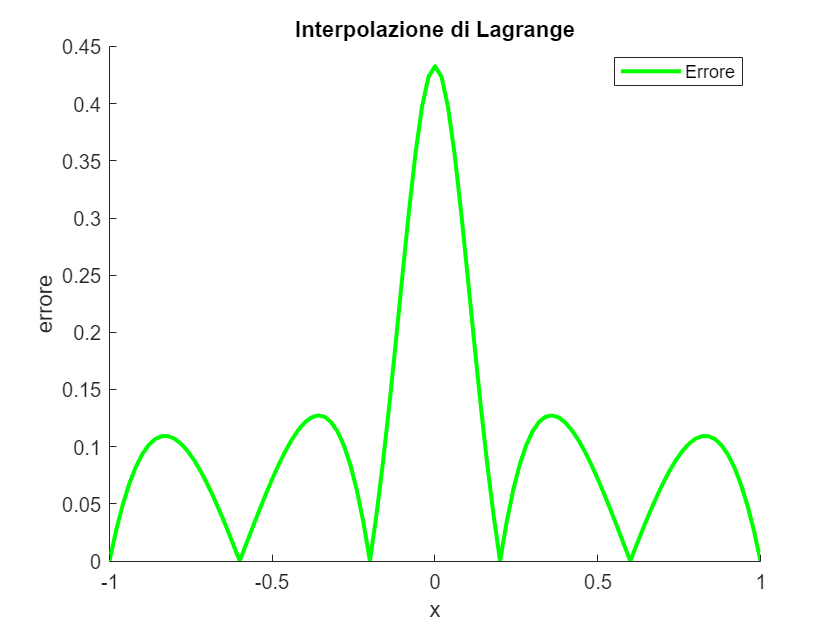


Errore Norma: 1.4610


errLagrange(x, yi, y1);

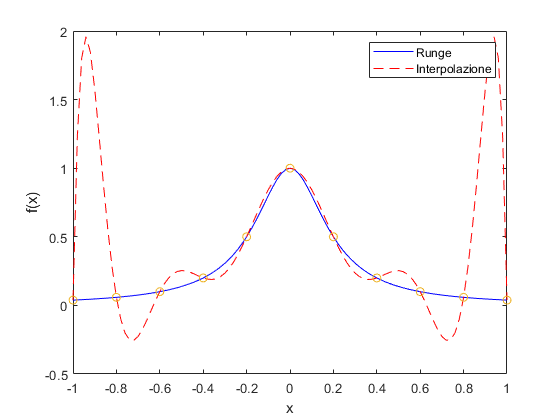

% Tabella di 11 punti 
table = funTable(y1, -1, 1, 11, 1);
yi = lagrange(x, table);
plot(x, y1(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('Runge', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

      x        f(x)         yi          Errore  
    _____    ________    _________    __________

       -1    0.038462     0.038462             0
    -0.98    0.039984       1.2303        1.1903
    -0.96    0.041597       1.8044        1.7628
    -0.94    0.043309        1.959        1.9156
    -0.92    0.045126       1.8458        1.8007
     -0.9    0.047059       1.5787        1.5317
    -0.88    0.049116       1.2402        1.1911
    -0.86    0.051308      0.88808       0.83677
    -0.84    0.053648      0.56044        0.5068
    -0.82    0.056148      0.28022       0.22407
     -0.8    0.058824     0.058824             0
    -0.78     0.06169     -0.10072       0.16241
    -0.76    0.064767      -0.2013       0.26606
    -0.74    0.068074     -0.24961       0.31768
    -0.72    0.071633      -0.2546       0.32624
     -0.7    0.075472      -0.

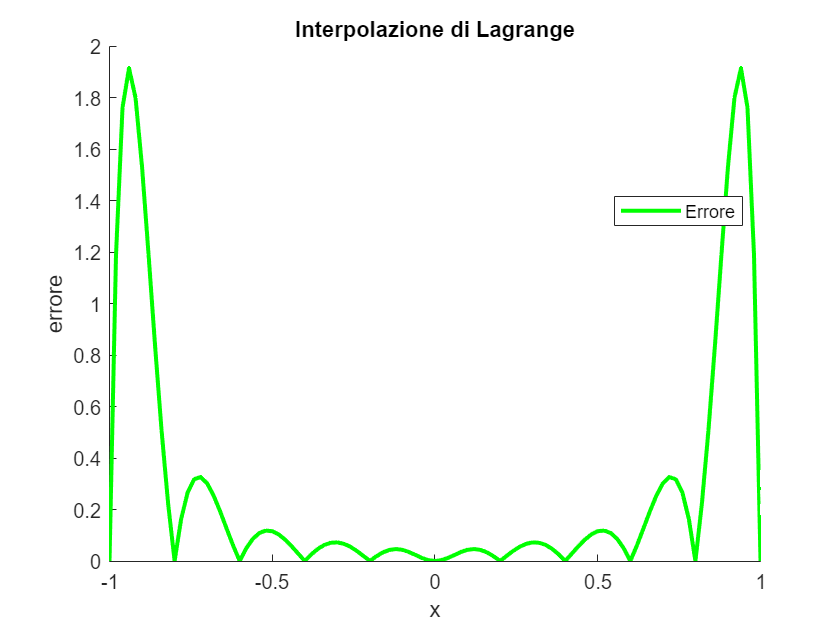


Errore Norma: 5.8019


errLagrange(x, yi, y1);

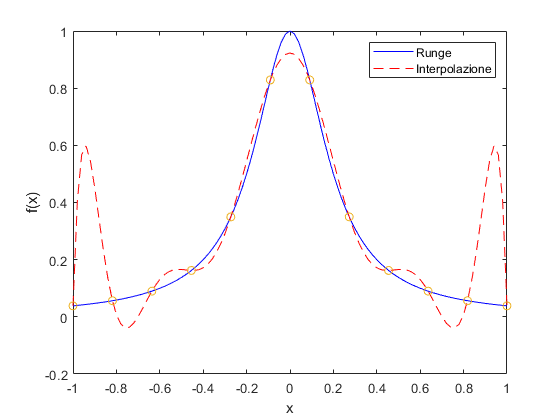


% Tabella di 12 punti 
table = funTable(y1, -1, 1, 12, 1);
yi = lagrange(x, table);
plot(x, y1(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('Runge', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

      x        f(x)          yi         Errore  
    _____    ________    __________    _________

       -1    0.038462      0.038462            0
    -0.98    0.039984       0.40409       0.3641
    -0.96    0.041597       0.56756      0.52596
    -0.94    0.043309       0.59779      0.55448
    -0.92    0.045126       0.54671      0.50159
     -0.9    0.047059       0.45242      0.40536
    -0.88    0.049116       0.34191      0.29279
    -0.86    0.051308       0.23335      0.18204
    -0.84    0.053648       0.13807     0.084422
    -0.82    0.056148      0.062213    0.0060648
     -0.8    0.058824     0.0080835      0.05074
    -0.78     0.06169     -0.024714     0.086405
    -0.76    0.064767     -0.038367      0.10313
    -0.74    0.068074      -0.03613       0.1042
    -0.72    0.071633     -0.021759     0.093392
     -0.7    0.075472    0.000

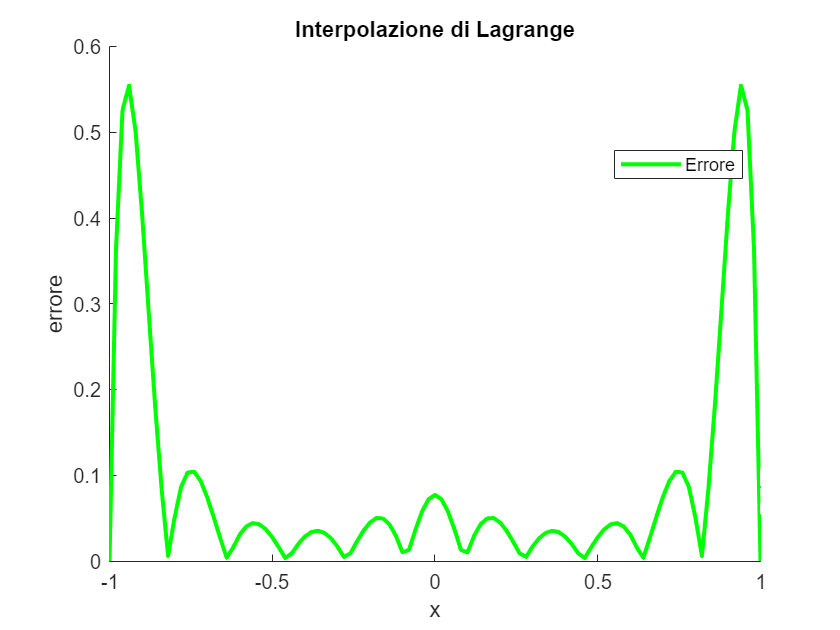


Errore Norma: 1.6414


errLagrange(x, yi, y1);

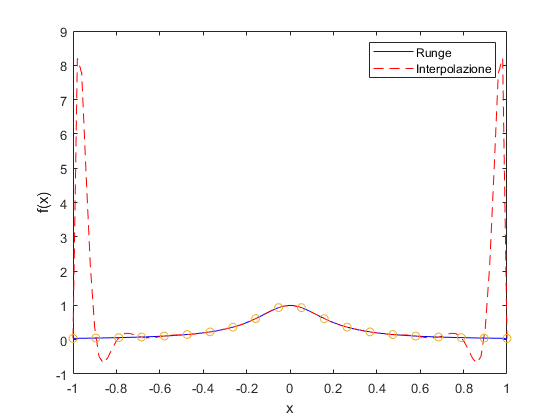

% Tabella di 20 punti 
table = funTable(y1, -1, 1, 20, 1);
yi = lagrange(x, table);
plot(x, y1(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('Runge', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

      x        f(x)         yi          Errore  
    _____    ________    _________    __________

       -1    0.038462     0.038462             0
    -0.98    0.039984       8.2065        8.1665
    -0.96    0.041597       7.7749        7.7333
    -0.94    0.043309       4.8826        4.8393
    -0.92    0.045126       2.1401         2.095
     -0.9    0.047059       0.3516       0.30454
    -0.88    0.049116     -0.49252       0.54163
    -0.86    0.051308     -0.68178       0.73308
    -0.84    0.053648     -0.52823       0.58188
    -0.82    0.056148     -0.26576        0.3219
     -0.8    0.058824    -0.030841      0.089665
    -0.78     0.06169      0.12039      0.058701
    -0.76    0.064767      0.18433       0.11957
    -0.74    0.068074      0.18386       0.11579
    -0.72    0.071633       0.1492      0.077565
     -0.7    0.075472      0.1

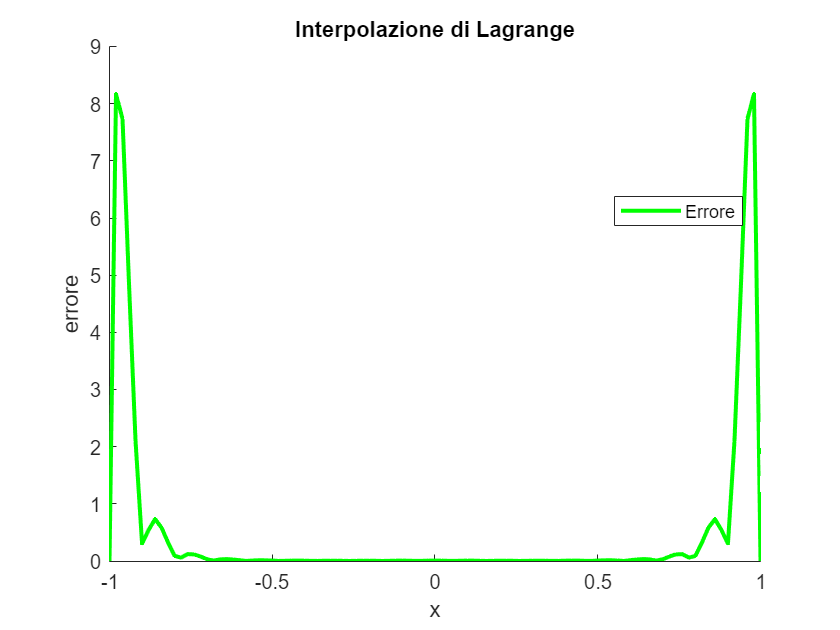


Errore Norma: 17.6476


errLagrange(x, yi, y1);

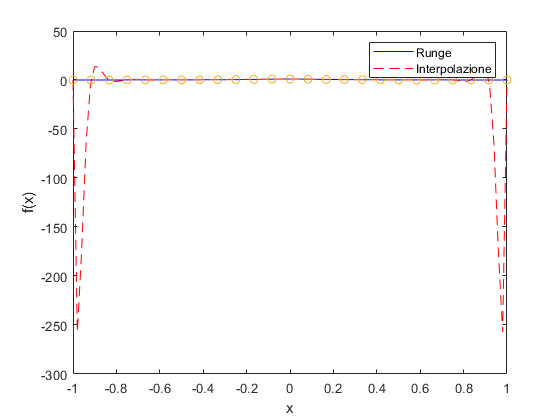

% Tabella di 25 punti 
table = funTable(y1, -1, 1, 25, 1);
yi = lagrange(x, table);
plot(x, y1(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('Runge', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

      x        f(x)         yi         Errore  
    _____    ________    ________    __________

       -1    0.038462    0.038462             0
    -0.98    0.039984     -257.17        257.21
    -0.96    0.041597     -173.49        173.53
    -0.94    0.043309     -65.648        65.692
    -0.92    0.045126     -5.4522        5.4973
     -0.9    0.047059      13.866        13.819
    -0.88    0.049116      12.881        12.832
    -0.86    0.051308       6.379        6.3277
    -0.84    0.053648      1.1543        1.1007
    -0.82    0.056148     -1.2368        1.2929
     -0.8    0.058824     -1.5272         1.586
    -0.78     0.06169    -0.89745       0.95914
    -0.76    0.064767    -0.18861       0.25338
    -0.74    0.068074     0.23592       0.16785
    -0.72    0.071633     0.35017       0.27854
     -0.7    0.075472     0.27673       0.20125

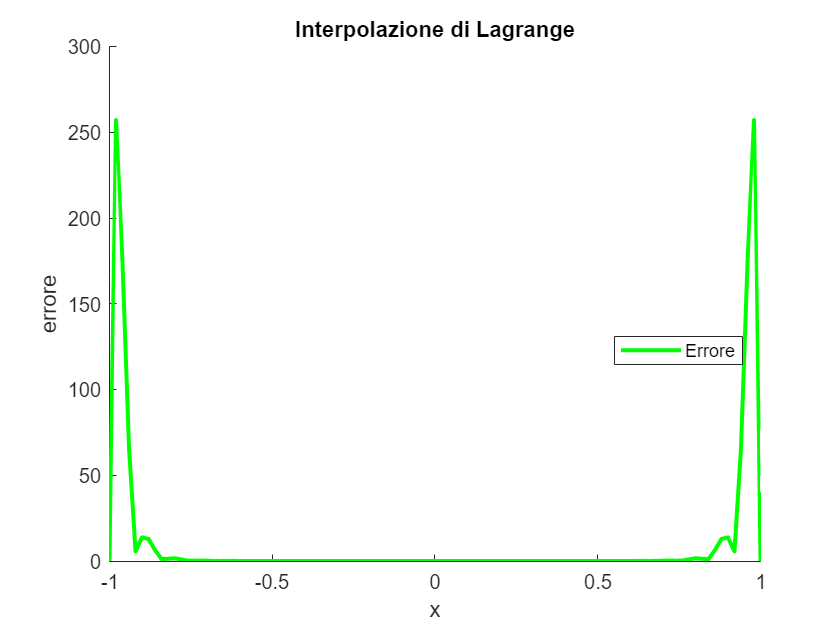


Errore Norma: 449.4839


errLagrange(x, yi, y1);

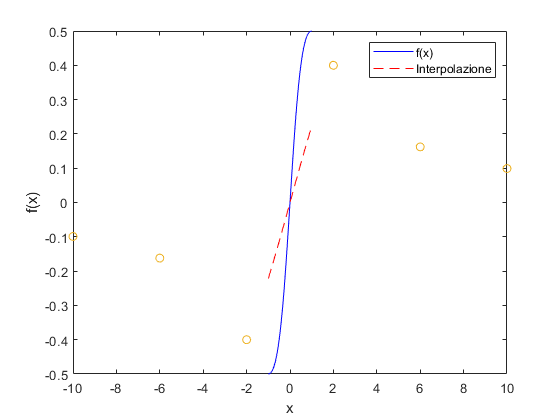

% Tabella di 5 punti 
table = funTable(y2, -10, 10, 6, 1);
yi = lagrange(x, table);
plot(x, y2(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('f(x)', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

      x        f(x)           yi           Errore  
    _____    _________    ___________    __________

       -1         -0.5       -0.22184       0.27816
    -0.98      -0.4999       -0.21769       0.28221
    -0.96     -0.49958       -0.21352       0.28606
    -0.94     -0.49904       -0.20934        0.2897
    -0.92     -0.49827       -0.20514       0.29313
     -0.9     -0.49724       -0.20093       0.29631
    -0.88     -0.49594       -0.19669       0.29925
    -0.86     -0.49437       -0.19245       0.30192
    -0.84      -0.4925       -0.18819       0.30431
    -0.82     -0.49031       -0.18391        0.3064
     -0.8      -0.4878       -0.17962       0.30819
    -0.78     -0.48495       -0.17531       0.30964
    -0.76     -0.48174       -0.17099       0.31075
    -0.74     -0.47816       -0.16666        0.3115
    -0.72     -0.47418       -0

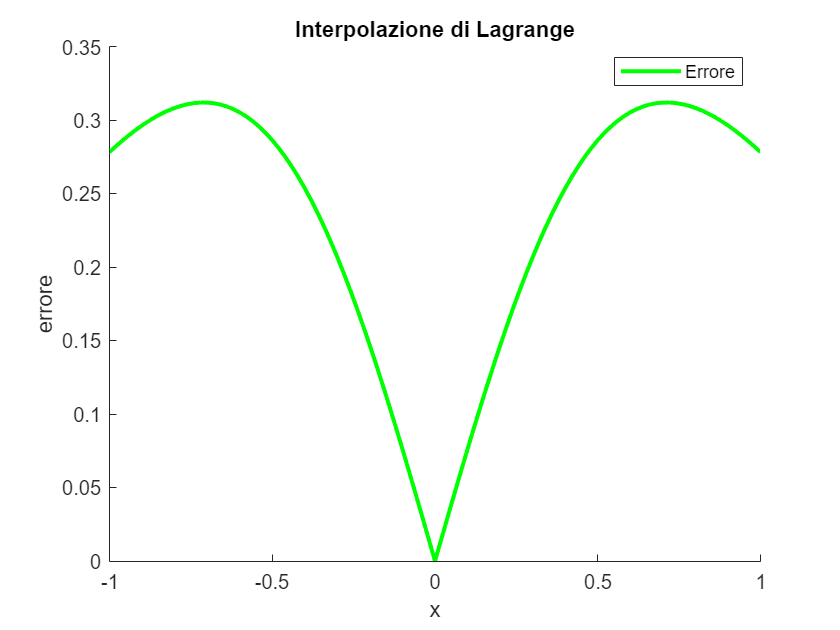


Errore Norma: 2.5234


errLagrange(x, yi, y2);

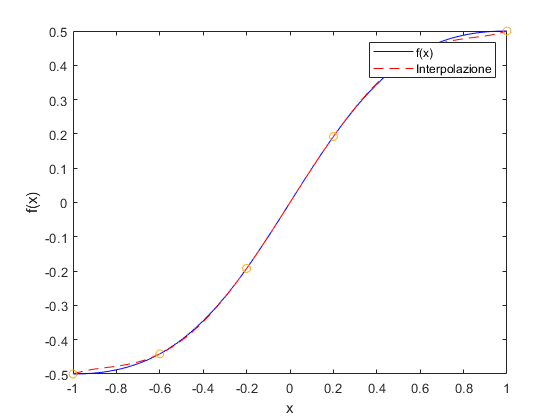

% Tabella di 6 punti 
table = funTable(y2, -1, 1, 6, 1);
yi = lagrange(x, table);
plot(x, y2(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('f(x)', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

      x        f(x)           yi           Errore  
    _____    _________    ___________    __________

       -1         -0.5           -0.5             0
    -0.98      -0.4999       -0.49603     0.0038672
    -0.96     -0.49958       -0.49273     0.0068552
    -0.94     -0.49904       -0.48997     0.0090704
    -0.92     -0.49827       -0.48765      0.010612
     -0.9     -0.49724       -0.48567      0.011572
    -0.88     -0.49594       -0.48391      0.012037
    -0.86     -0.49437       -0.48228      0.012085
    -0.84      -0.4925       -0.48071       0.01179
    -0.82     -0.49031        -0.4791      0.011218
     -0.8      -0.4878       -0.47738      0.010429
    -0.78     -0.48495       -0.47548     0.0094787
    -0.76     -0.48174       -0.47333      0.008415
    -0.74     -0.47816       -0.47088      0.007282
    -0.72     -0.47418       -0

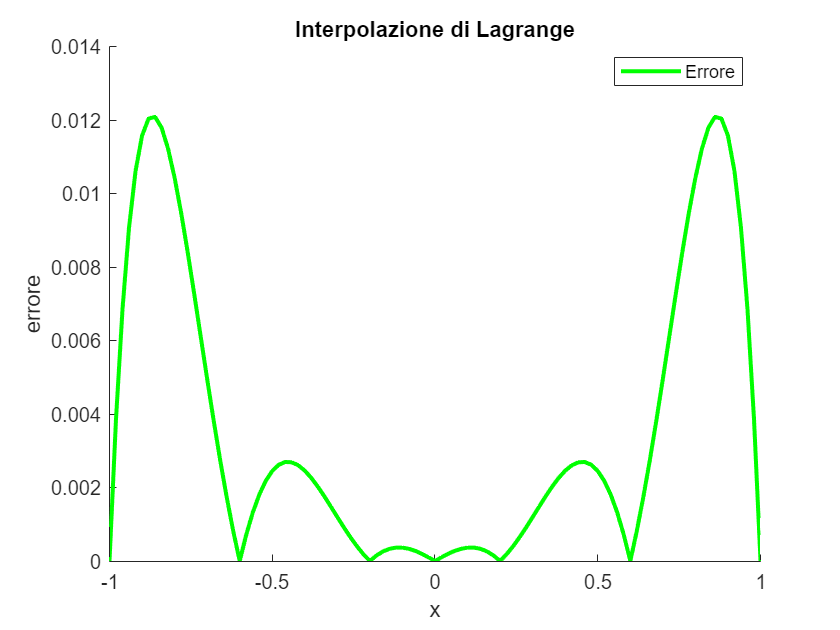


Errore Norma: 0.0534


errLagrange(x, yi, y2);

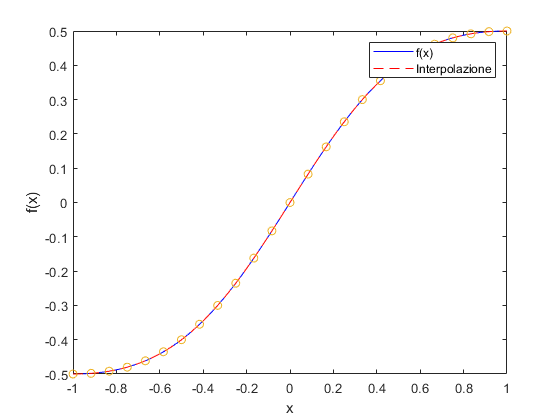

% Tabella di 25 punti 
table = funTable(y2, -1, 1, 25, 1);
yi = lagrange(x, table);
plot(x, y2(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('f(x)', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

      x        f(x)          yi          Errore  
    _____    _________    _________    __________

       -1         -0.5         -0.5             0
    -0.98      -0.4999      -0.4999    9.0249e-07
    -0.96     -0.49958     -0.49958     6.095e-07
    -0.94     -0.49904     -0.49904     2.309e-07
    -0.92     -0.49827     -0.49827    1.9329e-08
     -0.9     -0.49724     -0.49724    4.8588e-08
    -0.88     -0.49594     -0.49594    4.5096e-08
    -0.86     -0.49437     -0.49437    2.2219e-08
    -0.84      -0.4925      -0.4925    3.8596e-09
    -0.82     -0.49031     -0.49031    4.5257e-09
     -0.8      -0.4878      -0.4878    5.5389e-09
    -0.78     -0.48495     -0.48495    3.3403e-09
    -0.76     -0.48174     -0.48174    8.7944e-10
    -0.74     -0.47816     -0.47816    5.8031e-10
    -0.72     -0.47418     -0.47418    9.5864e-10
     -0.7    

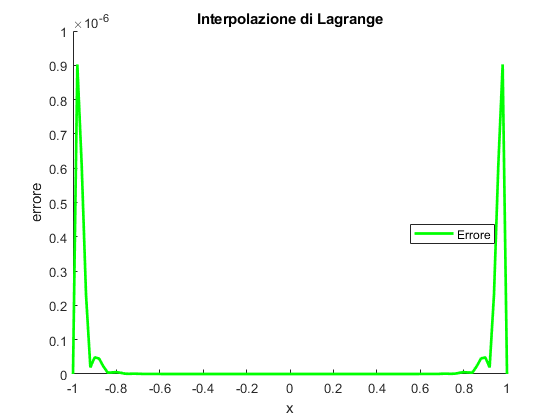


Errore Norma: 0.0000


errLagrange(x, yi, y2);